    clc; clear; close all;

Load Robot, Ik, Ur3, cam

Tee_mult = struct;
load("Workspace\robot.mat")
load("Workspace\cam_Param2.mat")
load("Workspace\scanPos.mat")
Tee_mult(1).T = load("Workspace\t_ee_mult1.mat");
Tee_mult(2).T = load("Workspace\t_ee_mult2.mat");
Tee_mult(3).T = load("Workspace\t_ee_mult3.mat");

ik = inverseKinematics('RigidBodyTree',robot);
eeName = robot.BodyNames{9};
weights = [0.5, 0.5, 0.5, 1, 1, 1];

cam = webcam('WEB CAM');

ur3 = tcpclient('192.168.32.3',30002);

q0 = getJointFromUR(ur3);
% a = preview(cam)

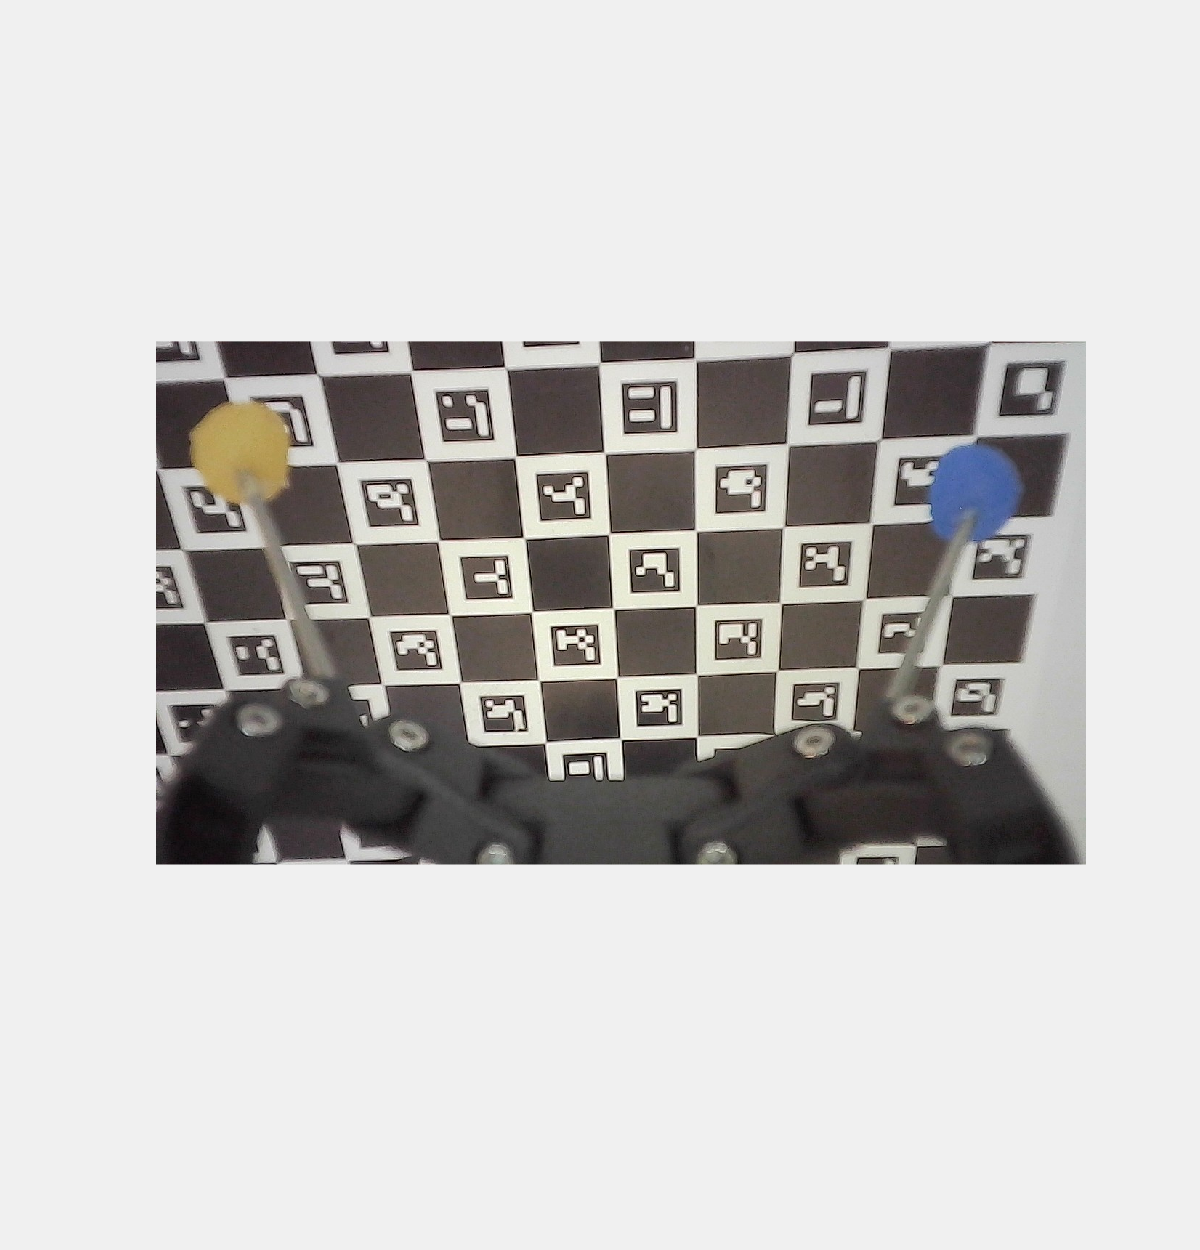

load("Workspace\dataEyeInHand\record0.mat")
img = dataRecord(1).img;
centroid = dataRecord(1).centroid;

fig = figure('Position',[1 1 1280 720],"Visible","on");
fig.Position = [1 1 1920/2  1000];
ax = axes(fig);
imgh = image(ax,zeros(size(img),'uint8'));
axis(ax,'image')
preview(cam,imgh)

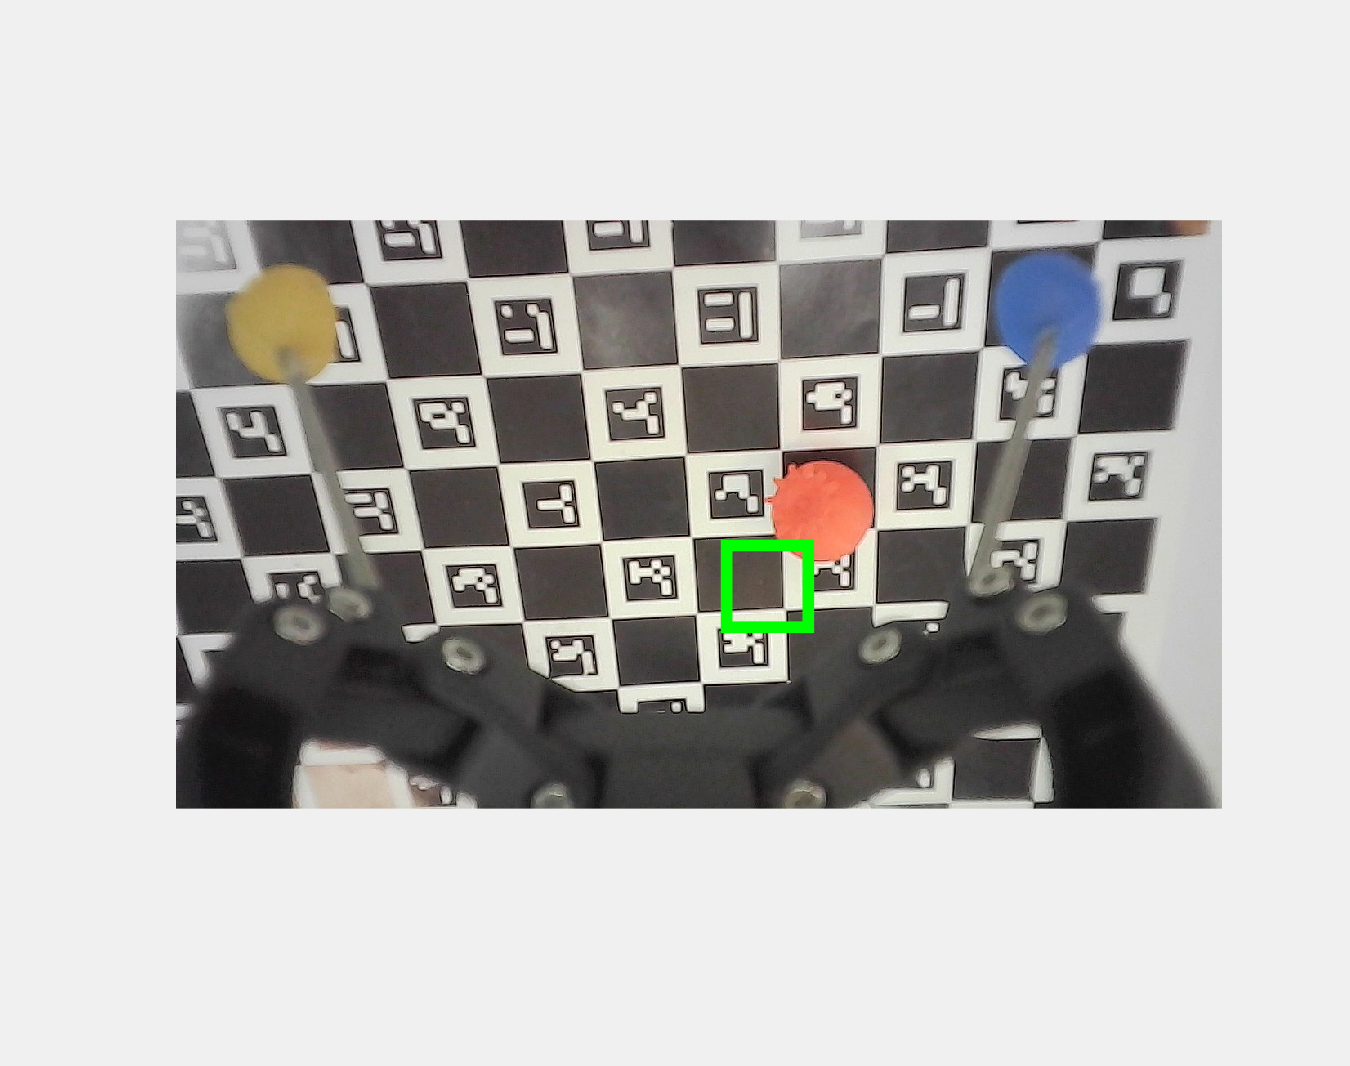

centroidHandle =   Rectangle with properties:

    FaceColor: 'none'
    EdgeColor: [0 1 0]
    LineWidth: 7
    LineStyle: '-'
    Curvature: [0 0]
     Position: [674.3012 398.3672 100 100]

  Show all properties


preview(cam,imgh)
hold(ax,"on")
centroidHandle = rectangle("Position",[centroid(1)-50 centroid(2)-50 100 100],'LineWidth',7,'EdgeColor',[0,1,0])

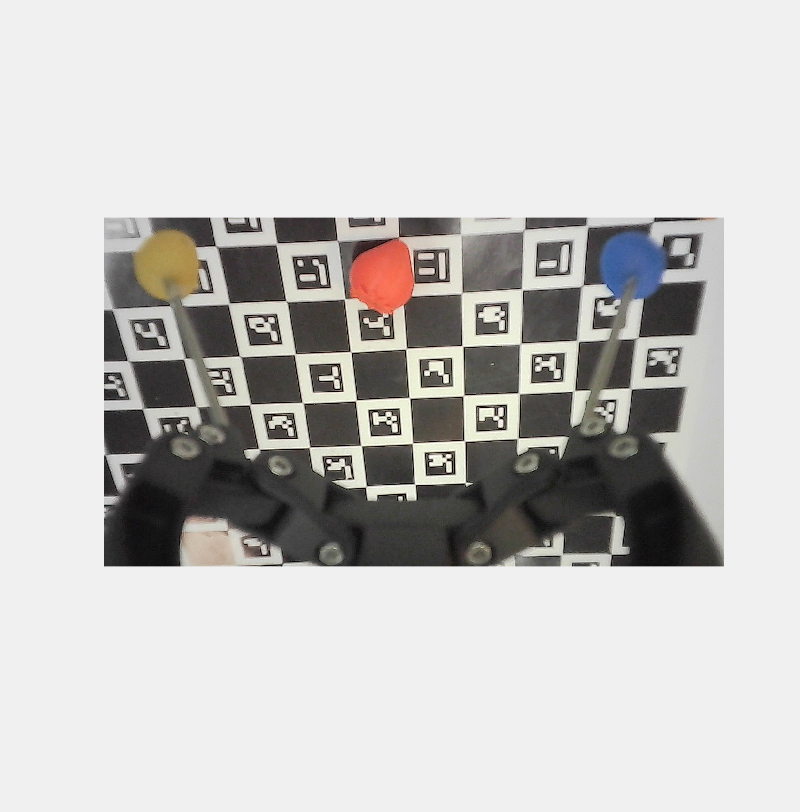

delete(centroidHandle)
hold(ax,"off")

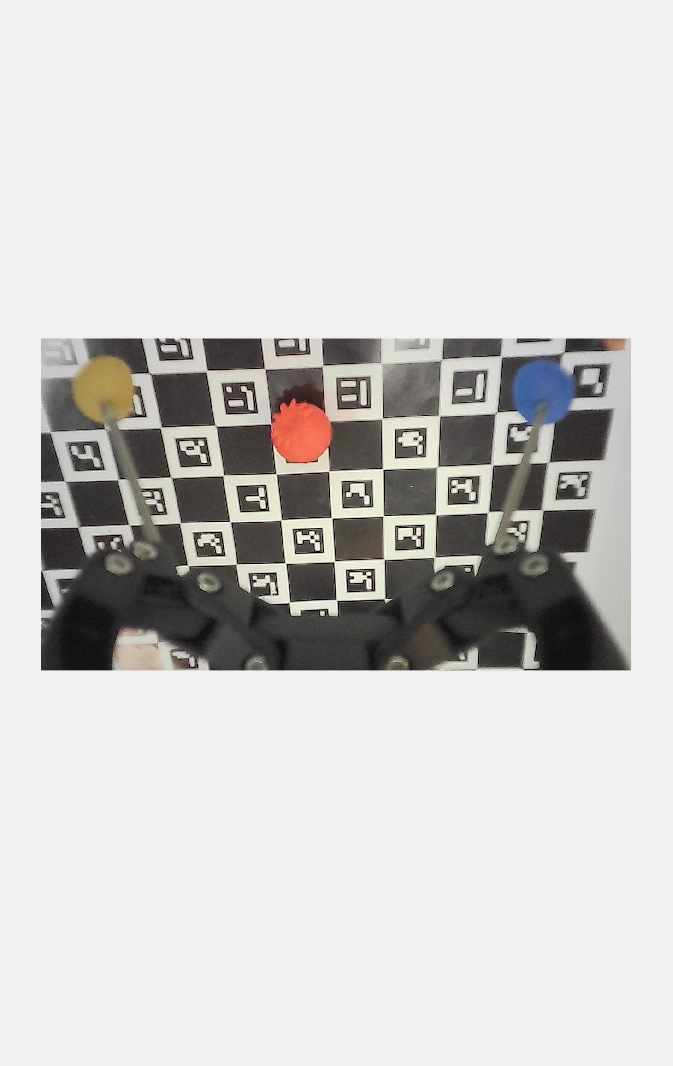

img = snapshot(cam);
figImgHadle = figure('Position',[1080/2 1 1280 720],"Visible","on");
imshow(img)
figImgHadle.Position = [1.8000   49.8000  538.4000  852.8000];
figImgHadle.CurrentAxes.Children.CData = zeros(720,1280);
figImgHadle.CurrentAxes.Children.CData = img;

figImgHadle2 = figure('Position',[1080/2 1 1280 720],"Visible","on");
show(robot,q0)

ans =   Axes (Primary) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


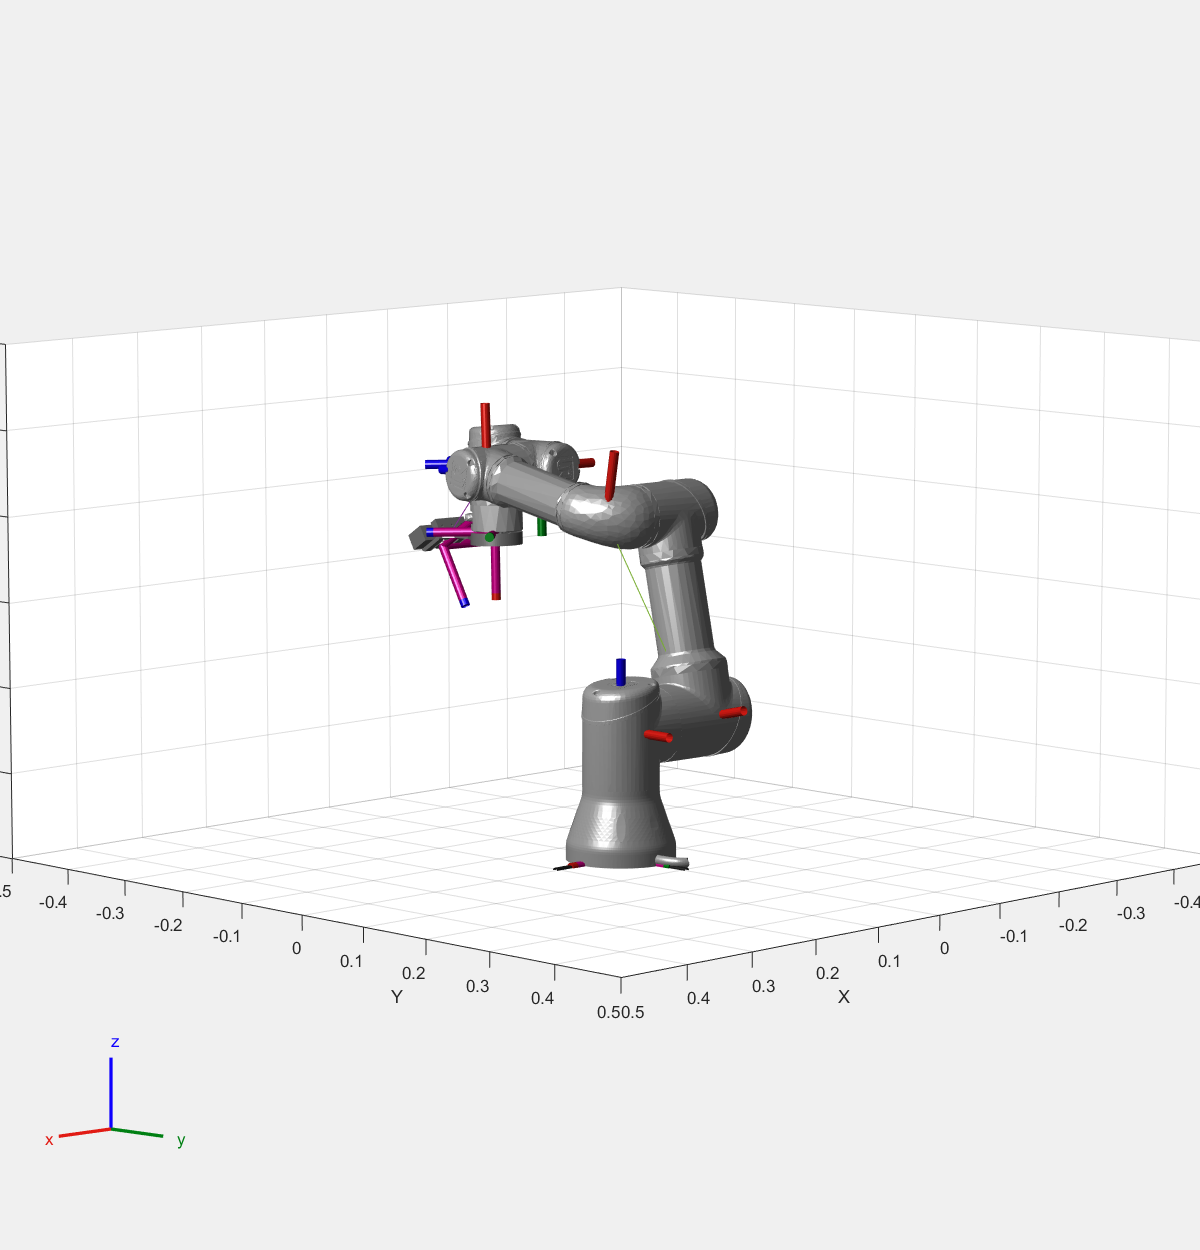

axx = gca;
figImgHadle2.Position = [1920/2+1   1  1920/2  1000];

axx.XLim = [-0.5 0.5];
axx.YLim = [-0.5 0.5];
axx.ZLim = [ 0   0.6];


% figImgHadle2.CurrentAxes.Children.CData = zeros(720,1280);
% 
% figImgHadle2.CurrentAxes.Children.CData = img;

dataRecord = struct;
count = 1;

Scan Strawberry

msg =     "def movepProc():
     movej([-1.6249,-1.7922,-1.1648,-1.7684,1.5918,-0.76655],v=1)
     end
     "


state = struct with fields:
    Centroid: [689.9292 368.2600]


centroidHandle =   Rectangle with properties:

    FaceColor: 'none'
    EdgeColor: [0 1 0]
    LineWidth: 7
    LineStyle: '-'
    Curvature: [0 0]
     Position: [639.9292 318.2600 100 100]

  Show all properties


ans =   Axes (Primary) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


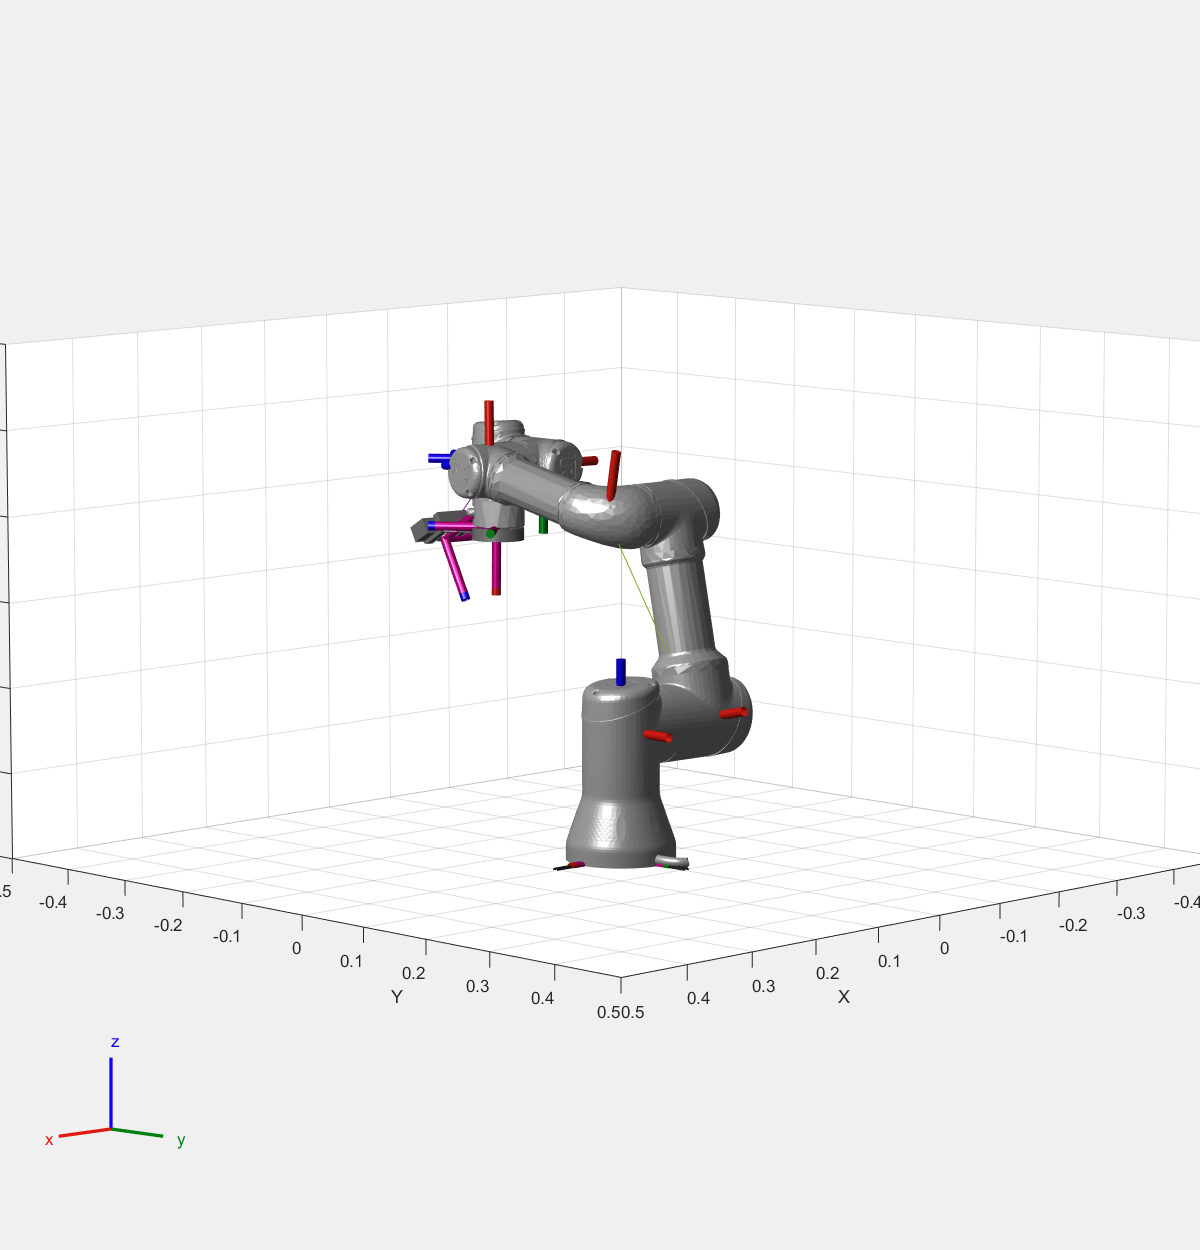

msg =     "def movepProc():
     movej([-1.6422,-1.4269,-1.5454,-1.7532,1.5904,-0.78514],v=1)
     end
     "


state = struct with fields:
    Centroid: [677.7935 53.2103]


centroidHandle =   Rectangle with properties:

    FaceColor: 'none'
    EdgeColor: [0 1 0]
    LineWidth: 7
    LineStyle: '-'
    Curvature: [0 0]
     Position: [627.7935 3.2103 100 100]

  Show all properties


ans =   Axes (Primary) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


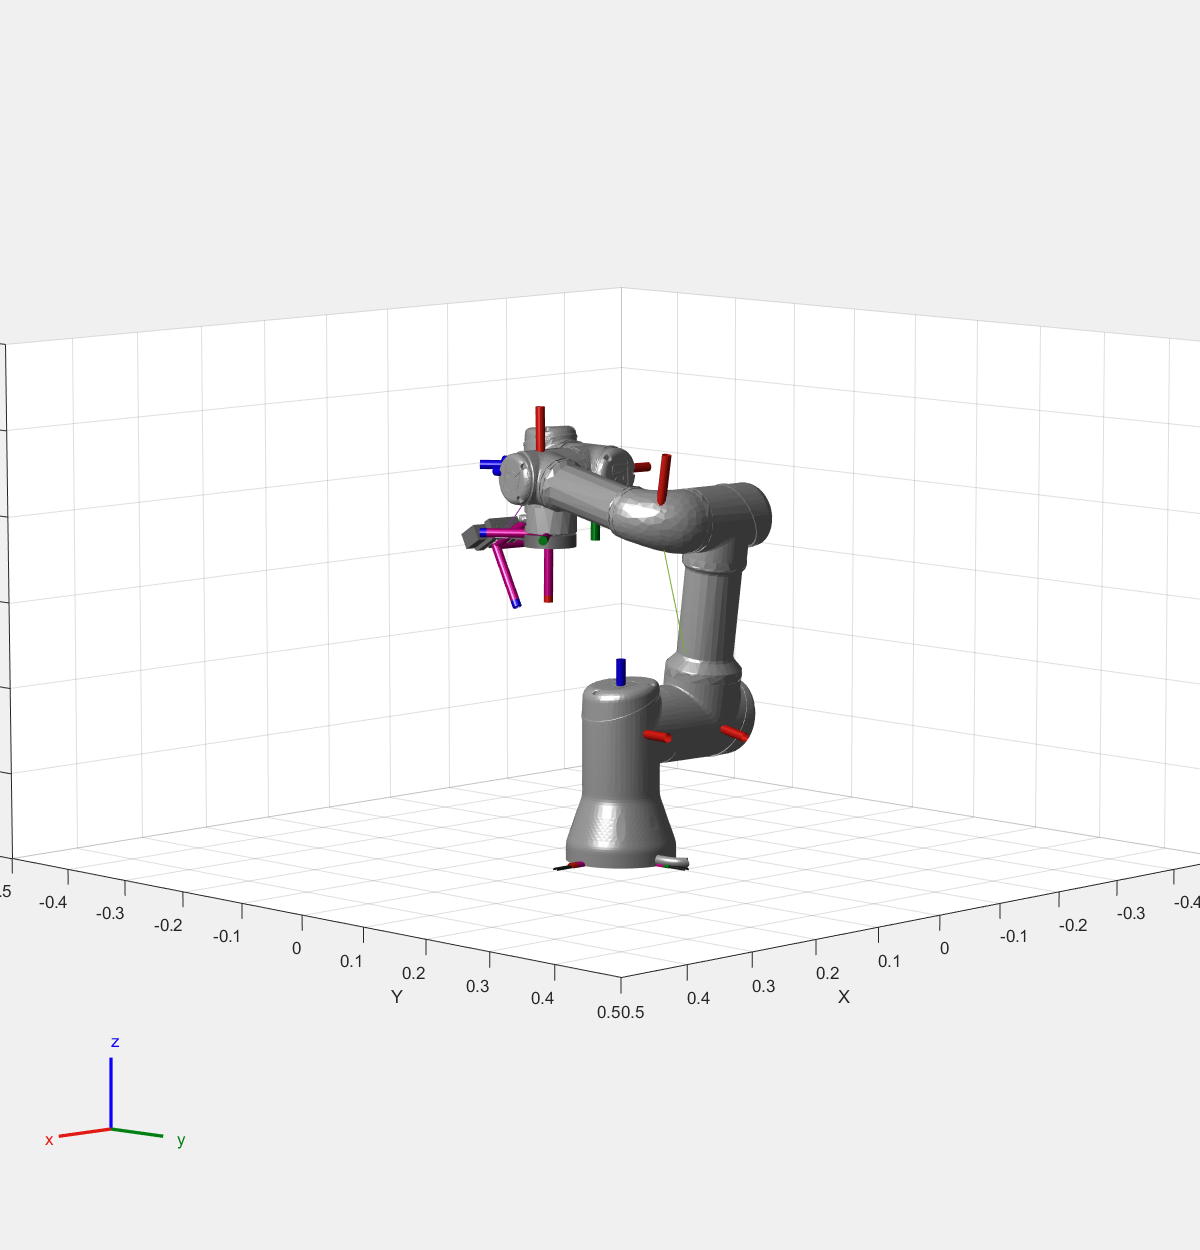

scanImg = struct;
v = 1;
scan = [1,4];
% dataRecord(count).run = 1;
for sc = scan    
    i = find(scan == sc);
    qScan = scanPos(sc).jPos;
    moveJoint(ur3,qScan,v);
    pause(2)

    img = snapshot(cam);
    [bw,~] = FindStrawberry(img);
    bw = imfill(bw,"holes");
    bw = bwareafilt(bw,1);
    bw = bwareaopen(bw,10);
    state = regionprops(bw, 'Centroid')
    scanImg(i).img = img;
    scanImg(i).bw = bw;
    dataRecord(count).time = datetime('now');
    dataRecord(count).img = img;
    
    if not(isempty(state))
        centroid = state.Centroid;
        preview(cam,imgh)
        hold(ax,"on")
        centroidHandle = rectangle("Position",[centroid(1)-50 centroid(2)-50 100 100],'LineWidth',7, 'EdgeColor',[0,1,0])
        textHandle = text(centroid(1)-200, centroid(2)+100, 'This area has strawberry', 'Color','green', 'FontSize',18, 'FontWeight','bold');
        scanImg(i).cantroid = centroid;
        dataRecord(count).centroid = centroid;
        pause(2)
        delete(centroidHandle);
        delete(textHandle);
        hold(ax,'off')
        
    end
    dataRecord(count).Jpos = getJointFromUR(ur3);
    dataRecord(count).pos = getPosFromUR(ur3);

    figImgHadle2 = figure('Position',[1080/2 1 1280 720],"Visible","on");
    show(robot,qScan)
    axx = gca;
    figImgHadle2.Position = [1920/2+1   1  1920/2  1000];%[1 49.8 1080 852.8]%[539   49.8000  538.4000  852.8000];
    count = count + 1;
    axx.XLim = [-0.5 0.5];
    axx.YLim = [-0.5 0.5];
    axx.ZLim = [ 0   0.6];
end

report section that found strawberry

C = {scanImg.cantroid};
idx = find(~cellfun(@isempty, C));
multivImg = struct;
addPos = struct;
delete(centroidHandle);

# Multi-view looking

for l = 1:length(idx)
k = idx(l);
qStart = scanPos(scan(k)).jPos;
moveJoint(ur3,qStart,v);
pause(2)

addCent = scanImg(k).cantroid;
[addCamPos,addPosRay] = mapStwRay(robot,qStart,addCent,cameraParams_new);
addPos(l).addCamPos = addCamPos;
addPos(l).addPosRay = addPosRay;

looking phase

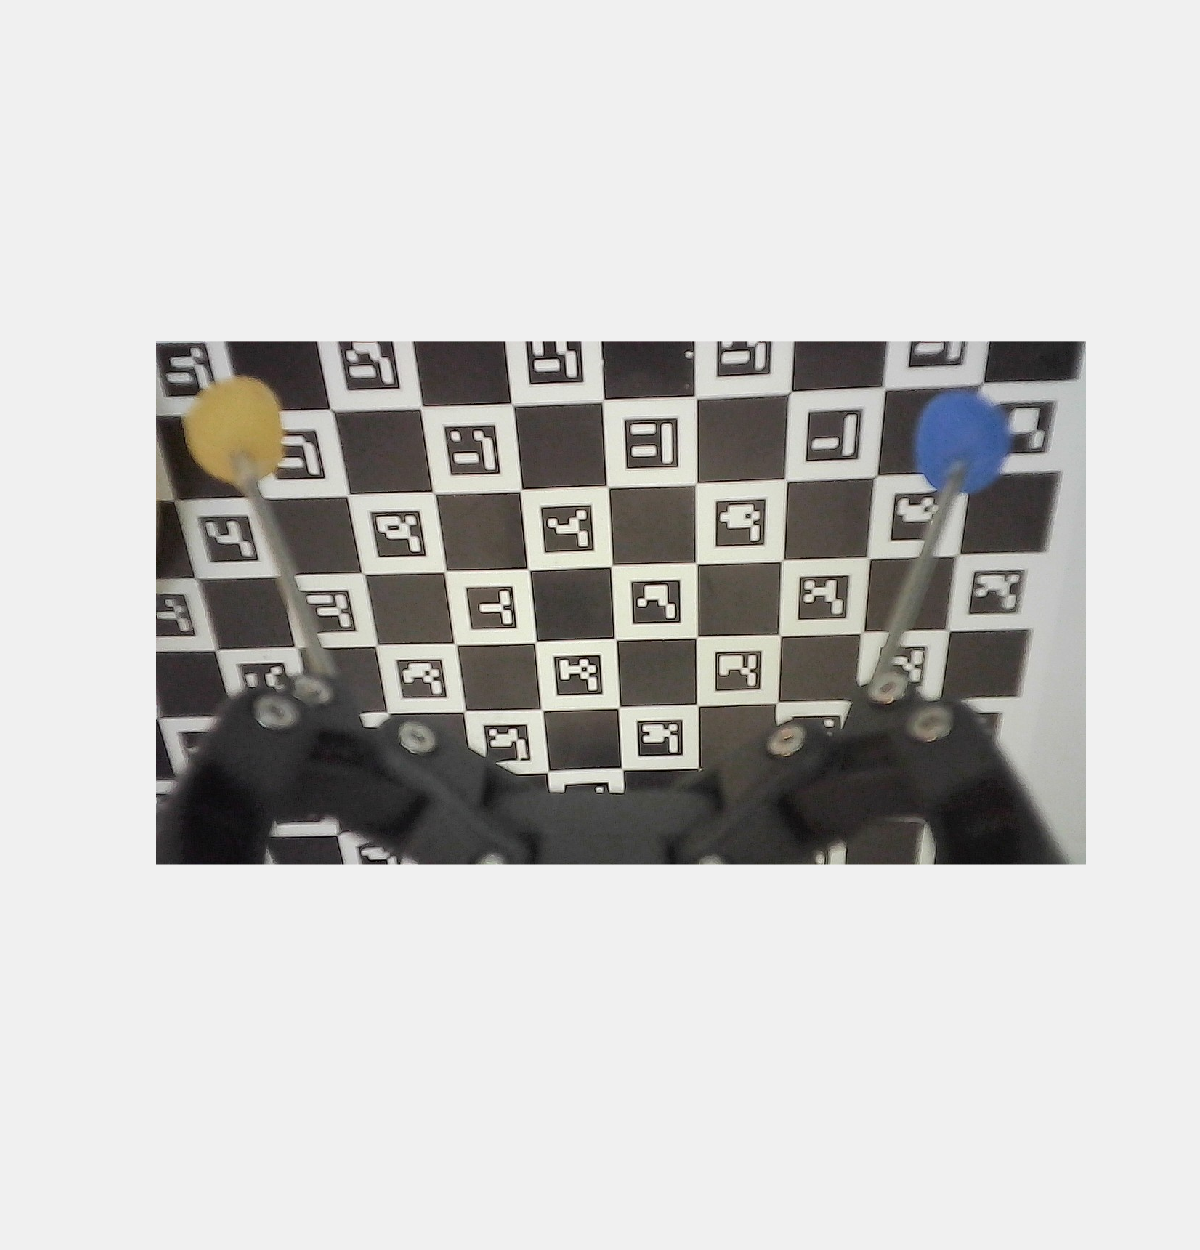

msg =     "def movepProc():
     movej([-1.6249,-1.7922,-1.1648,-1.7684,1.5918,-0.76655],v=1)
     end
     "


msg =     "def movepProc():
     movej([-1.9649,-2.0816,-0.96459,-1.8036,1.9733,-0.52932],v=1)
     end
     "


centroidHandle =   Rectangle with properties:

    FaceColor: 'none'
    EdgeColor: [0 1 0]
    LineWidth: 7
    LineStyle: '-'
    Curvature: [0 0]
     Position: [903.6280 316.2245 100 100]

  Show all properties


ans =   Axes (Primary) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


scaleFarPts = 0.0064

rayHandle =   Line with properties:

              Color: [1 0 0]
          LineStyle: '--'
          LineWidth: 5
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-0.2780 0.1850]
              YData: [-0.4219 -0.0028]
              ZData: [0.2554 -0.5256]

  Show all properties


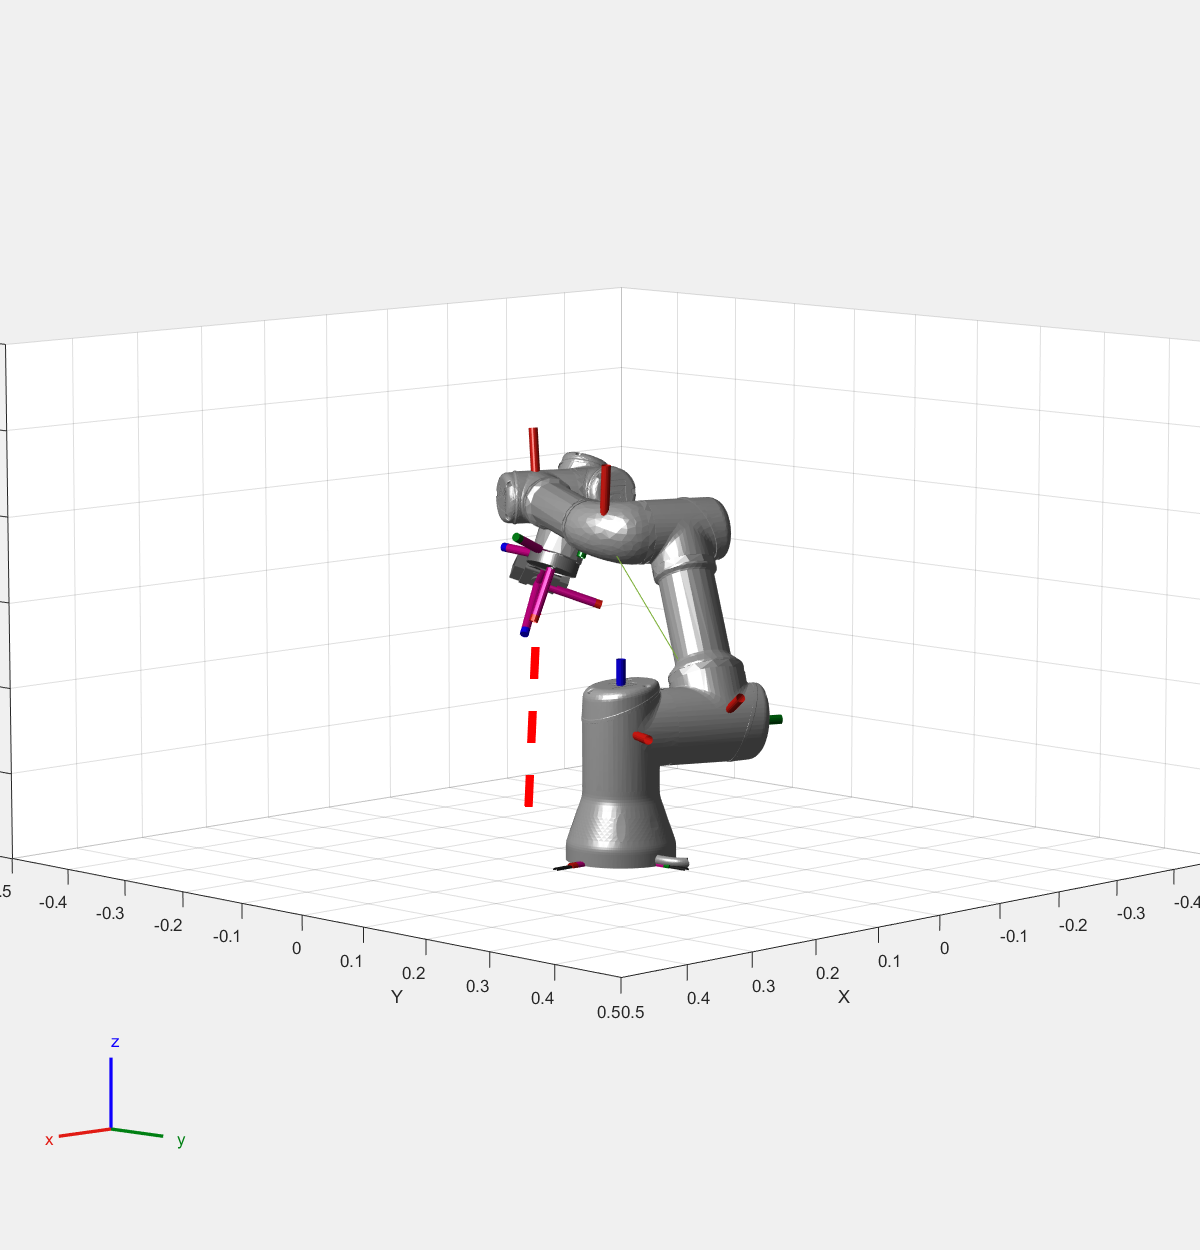

msg =     "def movepProc():
     movej([-1.6168,-2.1669,-0.66143,-2.1602,1.5797,-0.75459],v=1)
     end
     "


centroidHandle =   Rectangle with properties:

    FaceColor: 'none'
    EdgeColor: [0 1 0]
    LineWidth: 7
    LineStyle: '-'
    Curvature: [0 0]
     Position: [633.0064 214.9976 100 100]

  Show all properties


ans =   Axes (Primary) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


scaleFarPts = 0.0073

rayHandle =   Line with properties:

              Color: [1 0 0]
          LineStyle: '--'
          LineWidth: 5
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-0.1368 -0.1131]
              YData: [-0.4828 0.1257]
              ZData: [0.2689 -0.5243]

  Show all properties


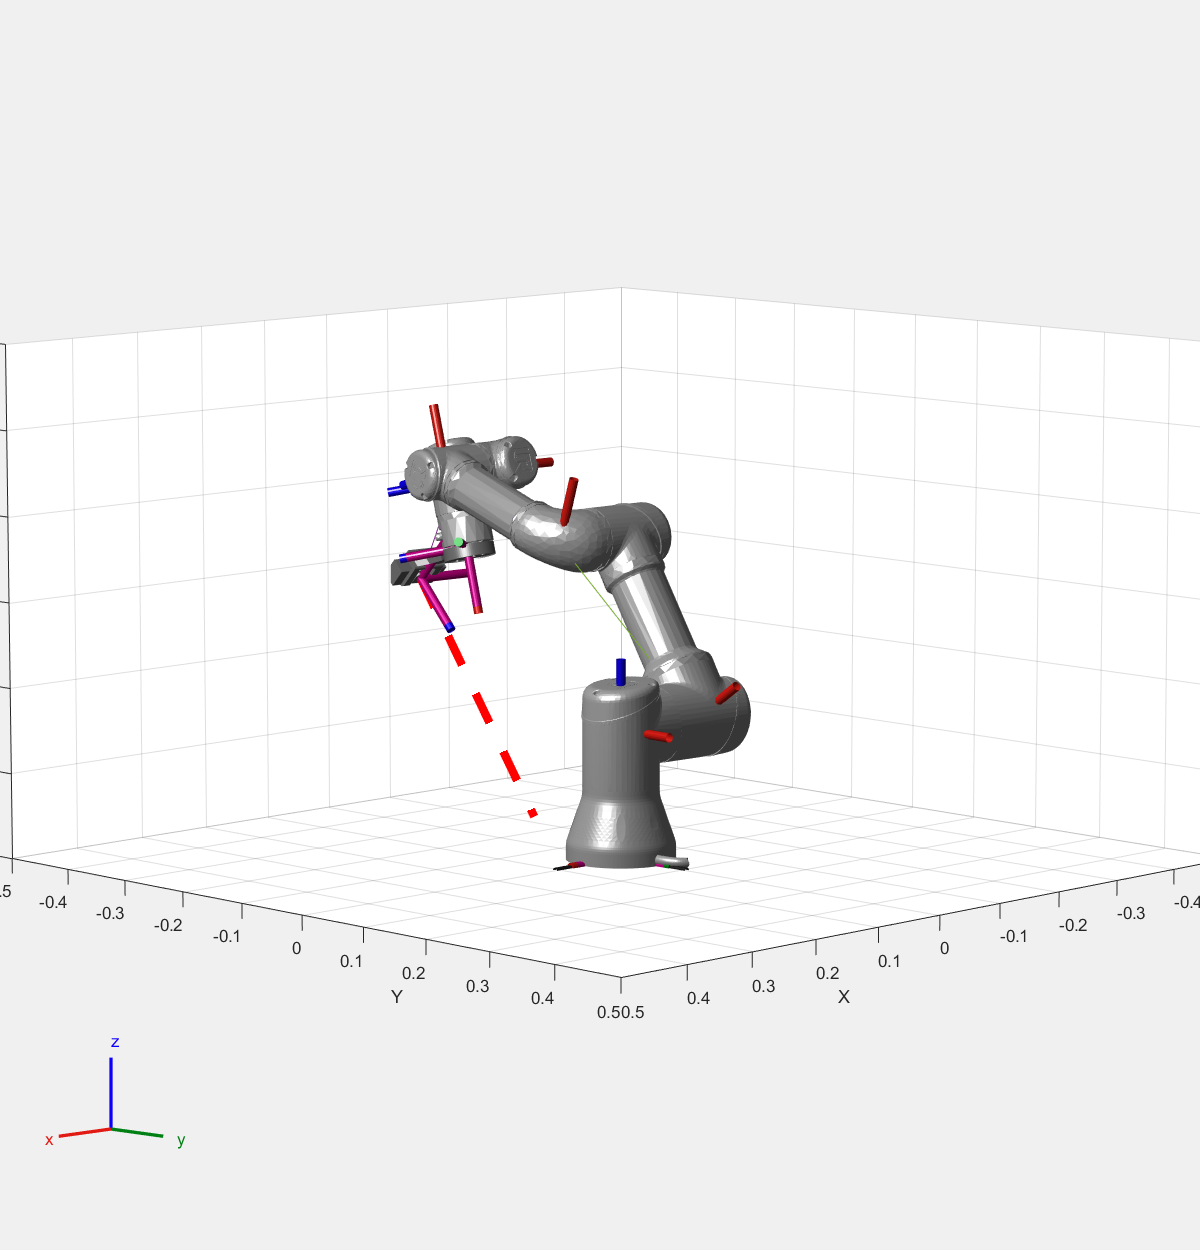

msg =     "def movepProc():
     movej([-1.0532,-1.6348,-1.4381,-1.7855,1.1966,-0.44902],v=1)
     end
     "


centroidHandle =   Rectangle with properties:

    FaceColor: 'none'
    EdgeColor: [0 1 0]
    LineWidth: 7
    LineStyle: '-'
    Curvature: [0 0]
     Position: [596.9106 372.7401 100 100]

  Show all properties


ans =   Axes (Primary) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


scaleFarPts = 0.0084

rayHandle =   Line with properties:

              Color: [1 0 0]
          LineStyle: '--'
          LineWidth: 5
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0.0373 -0.4016]
              YData: [-0.4308 -0.0500]
              ZData: [0.2997 -0.5142]

  Show all properties


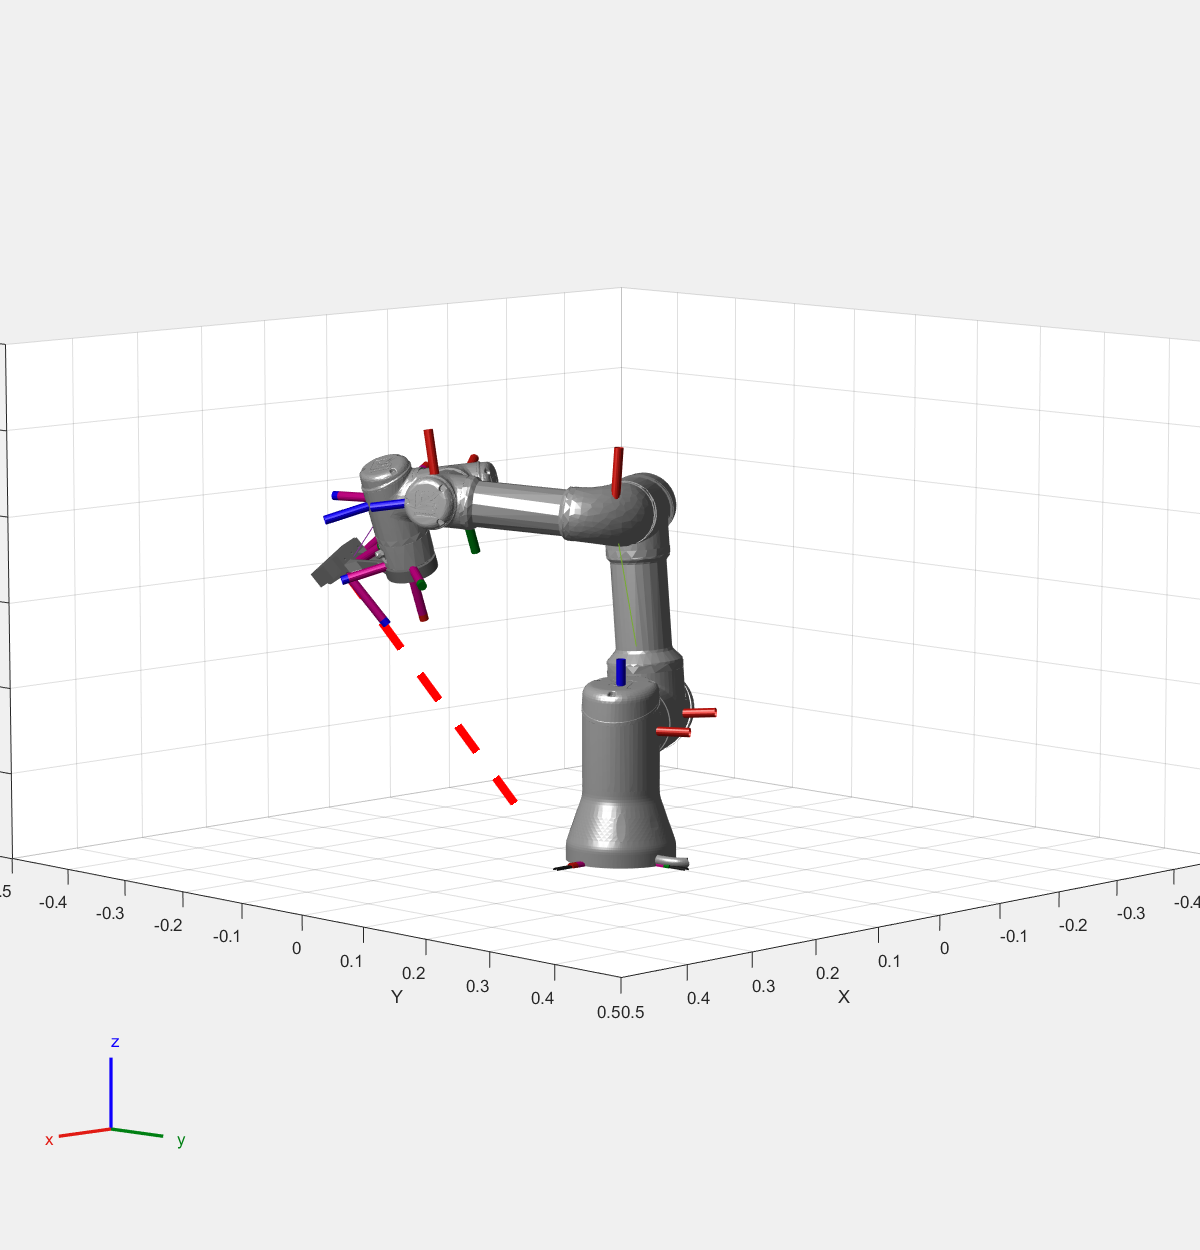

msg =     "def movepProc():
     movej([-1.6422,-1.4269,-1.5454,-1.7532,1.5904,-0.78514],v=1)
     end
     "


msg =     "def movepProc():
     movej([-2.0656,-1.7722,-1.379,-1.7398,1.9562,-0.63819],v=1)
     end
     "


centroidHandle =   Rectangle with properties:

    FaceColor: 'none'
    EdgeColor: [1 0 0]
    LineWidth: 7
    LineStyle: '-'
    Curvature: [0 0]
     Position: [691.5566 26.9879 100 100]

  Show all properties


ans =   Axes (Primary) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


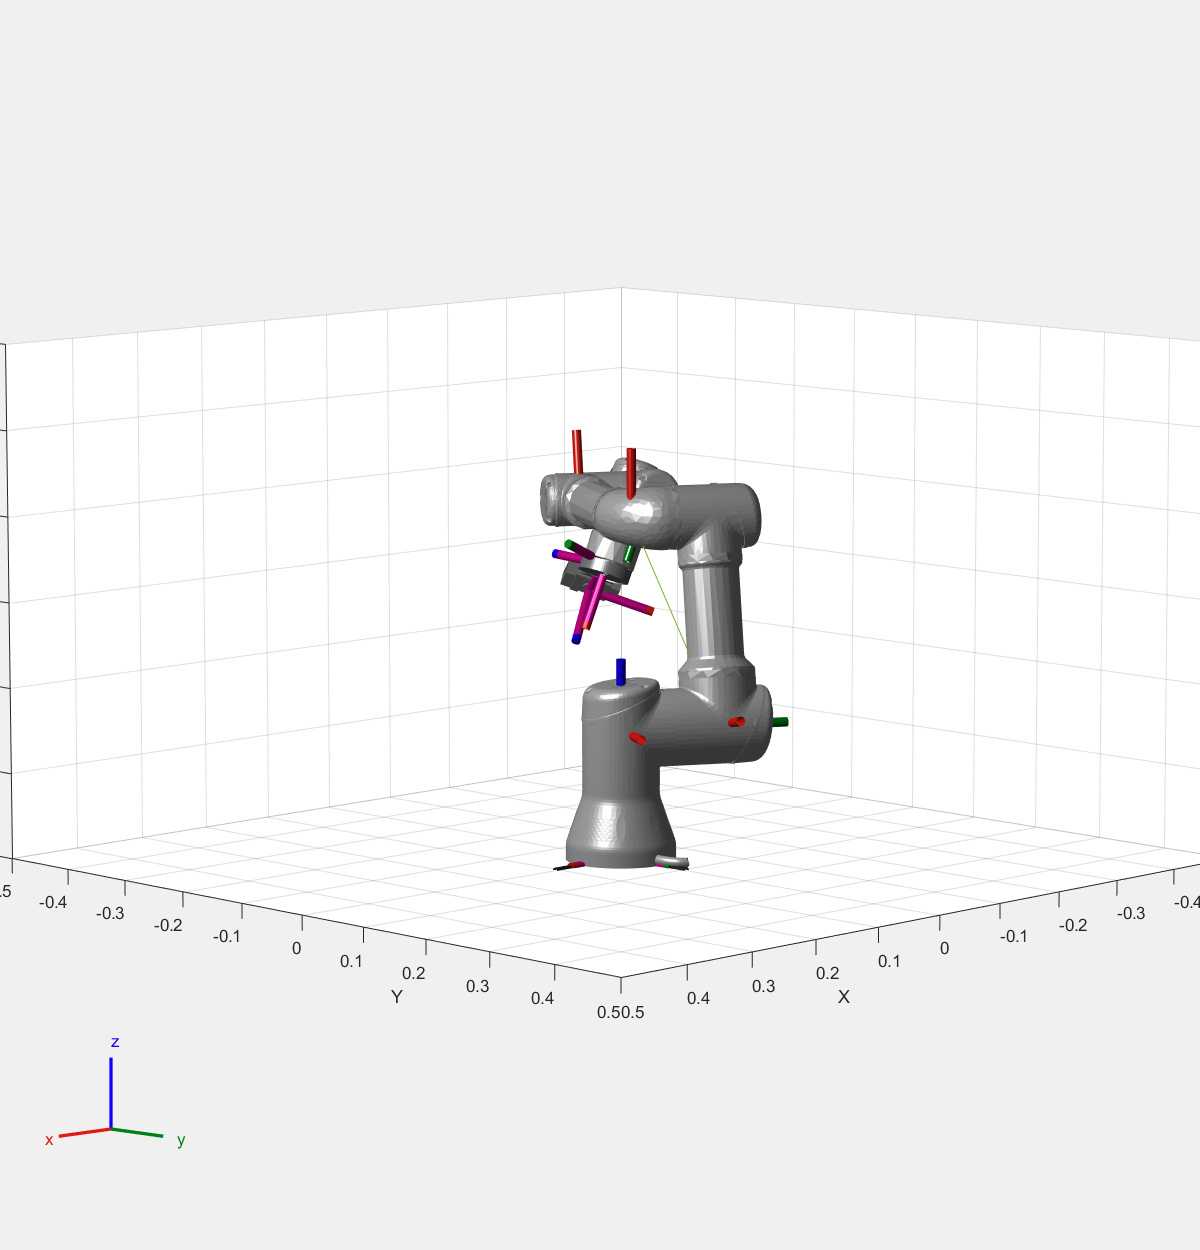

scaleFarPts = 0.0050

msg =     "def movepProc():
     movej([-1.628,-1.7338,-1.2803,-1.9743,1.5751,-0.76624],v=1)
     end
     "


centroidHandle =   Rectangle with properties:

    FaceColor: 'none'
    EdgeColor: [1 0 0]
    LineWidth: 7
    LineStyle: '-'
    Curvature: [0 0]
     Position: [610.7629 -39.6617 100 100]

  Show all properties


ans =   Axes (Primary) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


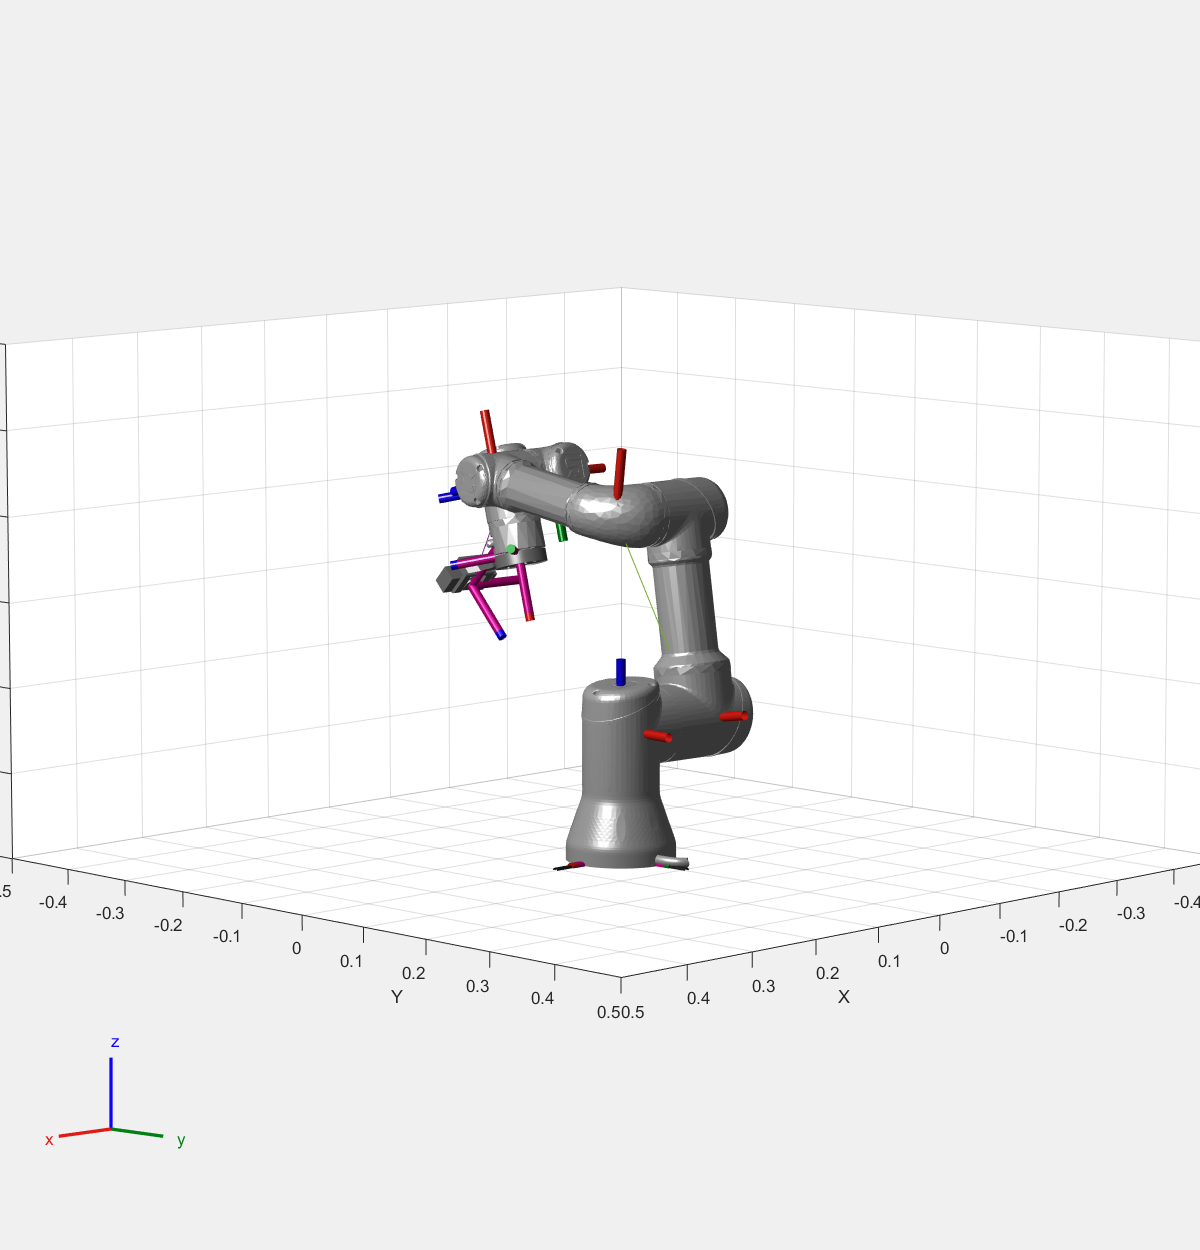

scaleFarPts = 0.0698

msg =     "def movepProc():
     movej([-0.85485,-1.2477,-1.7392,-1.9446,1.2315,-0.24194],v=1)
     end
     "


centroidHandle =   Rectangle with properties:

    FaceColor: 'none'
    EdgeColor: [0 1 0]
    LineWidth: 7
    LineStyle: '-'
    Curvature: [0 0]
     Position: [670.2805 65.6960 100 100]

  Show all properties


ans =   Axes (Primary) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


scaleFarPts = 0.0071

rayHandle =   Line with properties:

              Color: [1 0 0]
          LineStyle: '--'
          LineWidth: 5
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0.0376 -0.4303]
              YData: [-0.3406 -0.1226]
              ZData: [0.2997 -0.5567]

  Show all properties


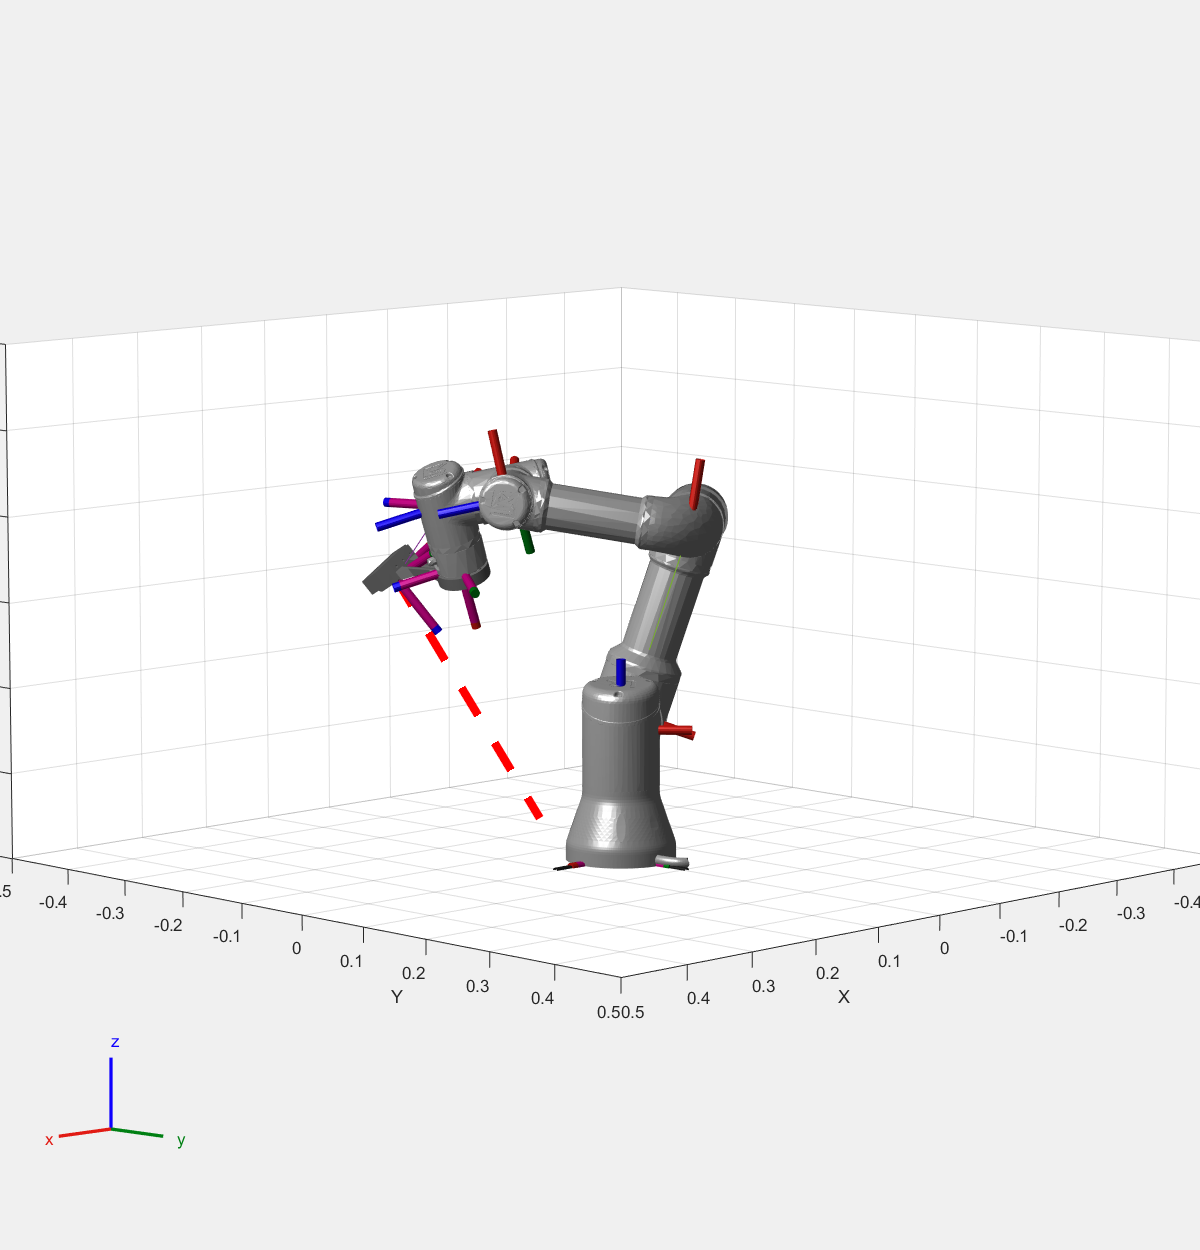

for j = 1:3
    n = (l-1)*3 + j;
    qMultiTest = calcMultiView(robot,ik,weights,qStart,Tee_mult(j).T.Tee_mult);
    moveJoint(ur3,qMultiTest,v);
    pause(2)
    
    img = snapshot(cam);
    dataRecord(count).time = datetime('now');
    dataRecord(count).img = img;
    dataRecord(count).Jpos = getJointFromUR(ur3);
    dataRecord(count).pos = getPosFromUR(ur3);
    multivImg(n).img = img;

    if ~(isempty(findCentroid(img)))
        [centroid,area] = findCentroid(img);
        [bw,~] = FindStrawberry(img);
        preview(cam,imgh)
        hold(ax,"on")
        if area>500
        if checkStrawberryInFrame(bw)
            multivImg(n).centroid = centroid;
            dataRecord(count).centroid = centroid;
            [camPos,posRay] = mapStwRay(robot,qMultiTest,centroid,cameraParams_new);
            multivImg(n).camPos = camPos;
            multivImg(n).posRay = posRay;
            multivImg(n).area = area;
        
            centroidHandle = rectangle("Position",[centroid(1)-50 centroid(2)-50 100 100],'LineWidth',7,'EdgeColor',[0,1,0])
            textHandle = text(centroid(1)-200, centroid(2)+100, 'Multi-View image saving', 'Color','green', 'FontSize',18, 'FontWeight','bold');
        else
            centroidHandle = rectangle("Position",[centroid(1)-50 centroid(2)-50 100 100],'LineWidth',7,'EdgeColor',[1,0,0])
            textHandle = text(centroid(1)-200, centroid(2)+100, 'Strawberry is out of frame', 'Color','red', 'FontSize',18, 'FontWeight','bold');
        end
        end
        pause(1)
    end

    % figImgHadle = figure('Position',[1080/2 1 1280 720],"Visible","on");
    % imshow(img)
    % figImgHadle.Position = [1.8000   49.8000  538.4000  852.8000];
    % figImgHadle.CurrentAxes.Children.CData = zeros(720,1280);
    % figImgHadle.CurrentAxes.Children.CData = img;
    % hold on
    % 
    % if ~(isempty(findCentroid(img)))
    %     plot(centroid(1),centroid(2),'.G','MarkerSize',20)
    % end
    % 
    figImgHadle2 = figure('Position',[1080/2 1 1280 720],"Visible","on");
    show(robot,qMultiTest)
    axx = gca;
    figImgHadle2.Position = [1920/2+1   1  1920/2  1000];%[1   49.8000  1080  852.8000];
    axx.XLim = [-0.5 0.5];
    axx.YLim = [-0.5 0.5];
    axx.ZLim = [ 0   0.6];

    if ~(isempty(findStwEdge(img)))
        [farPts,area] = findStwEdge(img);
        scaleFarPts = norm(farPts-centroid)/area
        [~,farRay] = mapStwRay(robot,qMultiTest,farPts,cameraParams_new); 
        if checkStrawberryInFrame(bw) && scaleFarPts > 0.006
            multivImg(n).farRay = farRay;
            hold on
            rayHandle = plot3([camPos(1),posRay(1)],[camPos(2),posRay(2)],[camPos(3),posRay(3)],'LineWidth',5,'Color','red','LineStyle','--')
            hold off
        end

    % 
    %     plot(farPts(1),farPts(2),'.Y','MarkerSize',20)
    end 
    % hold off

    count = count + 1;
    delete(centroidHandle)
    delete(textHandle)
    hold(ax,'off')
end
end

Calculate strawpos + orientation

delete(centroidHandle)
preview(cam,imgh)

stwPos = findStrawberryPose(multivImg);
farStw = findFarStwPos(multivImg);
targPos = se3([0,pi/2,pi/4],'eul',[stwPos(1),stwPos(2), 0.3]);
release(ik);
qTarget = ik(eeName,tform(targPos),weights,qStart);

graspPos = se3([0,pi/2,pi/4],'eul',[stwPos(1),stwPos(2), 0.207]);
release(ik);
qEnd = ik(eeName,tform(graspPos),weights,qTarget);

dxy = [farStw(1)-stwPos(1), farStw(2)-stwPos(2)];
r = norm(dxy);
alpha = atan(dxy(2)/dxy(1));
if dxy(1) > 0 && dxy(2) > 0
    theta = alpha;
elseif dxy(1) < 0 && dxy(2) > 0
    theta = pi+alpha;
elseif dxy(1) < 0 && dxy(2) < 0
    theta = pi+alpha;
else
    theta = alpha;
end
theta

theta = -0.9106


if theta > pi
    theta = theta-2*pi;
    qTargetN = qTarget + [0,0,0,0,0,theta];
    qEndN = qEnd + [0,0,0,0,0,theta];
else
    qTargetN = qTarget + [0,0,0,0,0,theta+pi];
    qEndN = qEnd + [0,0,0,0,0,theta+pi];
end


Rz = eul2rotm([theta,0,0], 'ZYX');
Ry = eul2rotm([0, deg2rad(35), 0], 'ZYX');
Rotat = Rz*Ry; 
L = 0.1;
xLocal = Rotat*[L;0;0];
yLocal = Rotat*[0;L;0];
zLocal = Rotat*[0;0;L];
figImgHadle2 = figure('Position',[1080/2 1 1280 720],"Visible","on");
show(robot,qTarget)

ans =   Axes (Primary) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


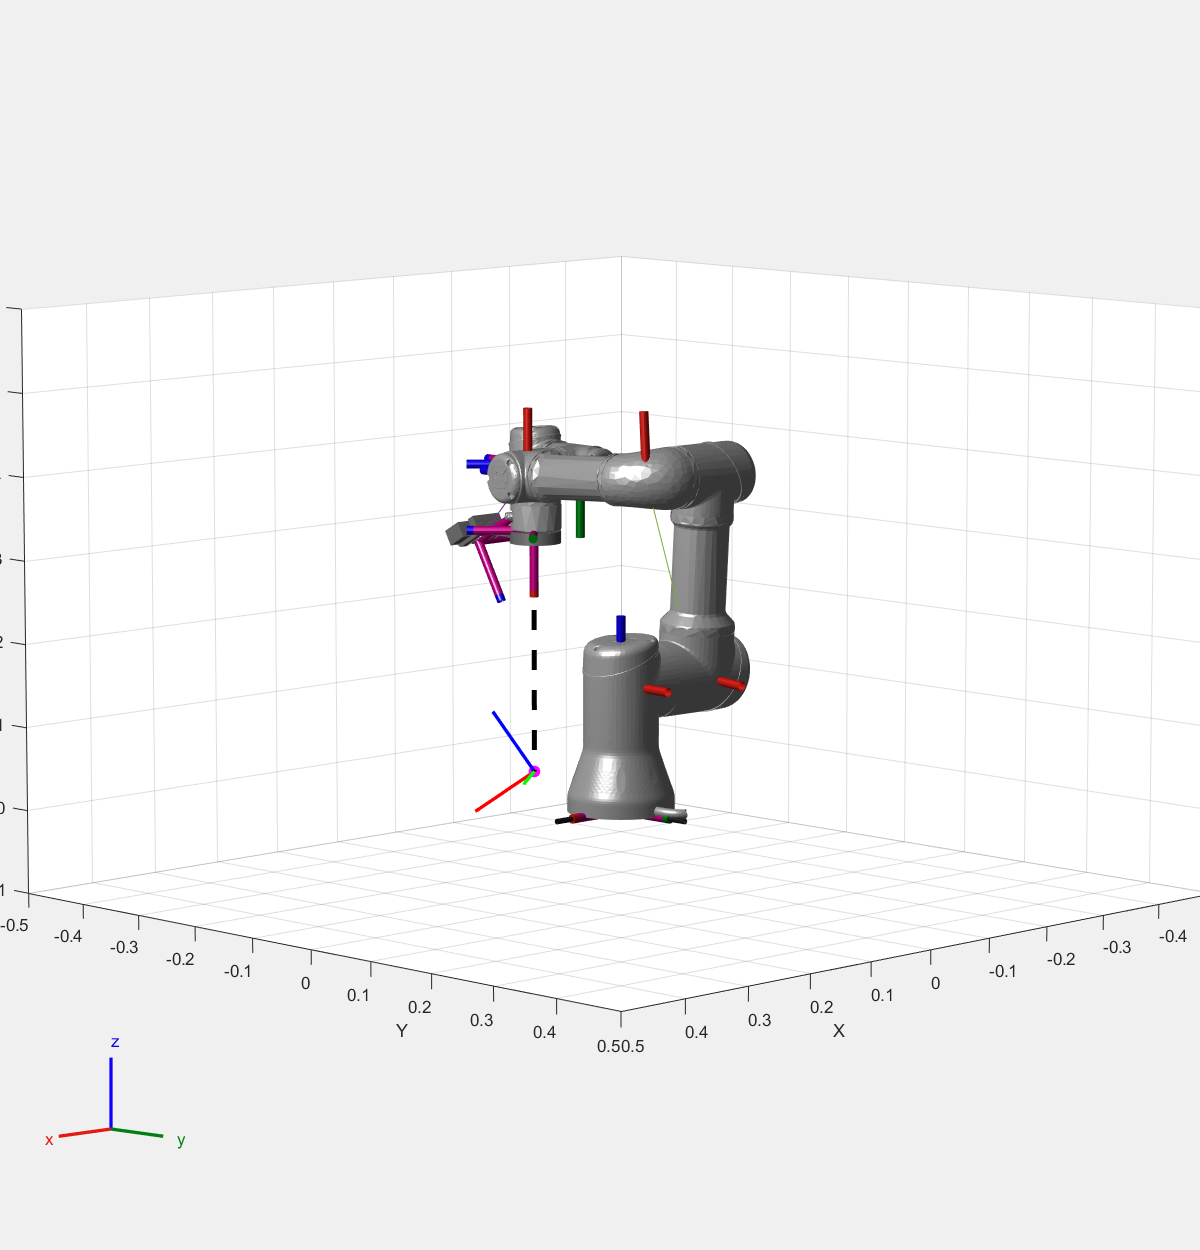

axx = gca;
figImgHadle2.Position = [1920/2+1   1  1920/2  1000];
axx.XLim = [-0.5 0.5];
axx.YLim = [-0.5 0.5];
axx.ZLim = [ -0.1   0.6];

hold on
plot3([stwPos(1),stwPos(1)],[stwPos(2),stwPos(2)],[0.3,0],'LineWidth',3,'Color','black','LineStyle','--')
scatter3(stwPos(1),stwPos(2),0,50,'magenta','filled');
%scatter3(farStw(1),farStw(2),0,50,'black','filled');
quiver3(stwPos(1),stwPos(2),0, xLocal(1), xLocal(2), xLocal(3), 'r', 'LineWidth', 2); % X axis
quiver3(stwPos(1),stwPos(2),0, yLocal(1), yLocal(2), yLocal(3), 'g', 'LineWidth', 2); % Y axis
quiver3(stwPos(1),stwPos(2),0, zLocal(1), zLocal(2), zLocal(3), 'b', 'LineWidth', 2); % Z axis
hold off

Grasping stanby phase

rp2040Send("cylinder off")

moveJoint(ur3,qTarget,v);

msg =     "def movepProc():
     movej([-1.62,-1.5087,-1.6947,-1.5089,1.5708,-0.83455],v=1)
     end
     "


pause(5)

moveJoint(ur3,qTargetN,v);

msg =     "def movepProc():
     movej([-1.62,-1.5087,-1.6947,-1.5089,1.5708,1.3964],v=1)
     end
     "


pause(5)

img = snapshot(cam);
dataRecord(count).time = datetime('now');
dataRecord(count).img = img;
dataRecord(count).Jpos = getJointFromUR(ur3);
dataRecord(count).pos = getPosFromUR(ur3);
dataRecord(count).centroid = findCentroid(img);
count = count + 1;

rp2040Send('servo_l 70')
rp2040Send('servo_r -160')
rp2040Send('servo_l 20')
rp2040Send('servo_r -100')

grasping phase

moveJoint(ur3,qEndN,v);

msg =     "def movepProc():
     movej([-1.62,-1.6236,-2.0399,-1.0489,1.5708,1.3964],v=1)
     end
     "


pause(1)
rp2040Send("cylinder on")
img = snapshot(cam);
dataRecord(count).time = datetime('now');
dataRecord(count).img = img;
dataRecord(count).Jpos = getJointFromUR(ur3);
dataRecord(count).pos = getPosFromUR(ur3);
dataRecord(count).centroid = findCentroid(img);
count = count + 1;

move target

moveJoint(ur3,qTarget,v);

msg =     "def movepProc():
     movej([-1.62,-1.5087,-1.6947,-1.5089,1.5708,-0.83455],v=1)
     end
     "


pause(3)

img = snapshot(cam);
dataRecord(count).time = datetime('now');
dataRecord(count).img = img;
dataRecord(count).Jpos = getJointFromUR(ur3);
dataRecord(count).pos = getPosFromUR(ur3);
dataRecord(count).centroid = findCentroid(img);
count = count + 1;

placePos = se3([0,pi/2,pi/4],'eul',[0.130,-0.345, 0.3]);
release(ik);
qPlace = ik(eeName,tform(placePos),weights,qTarget);

moveJoint(ur3,qPlace,v);

msg =     "def movepProc():
     movej([-0.90078,-1.7888,-1.3898,-1.5338,1.5708,-0.11538],v=1)
     end
     "


pause(2)
img = snapshot(cam);
dataRecord(count).time = datetime('now');
dataRecord(count).img = img;
dataRecord(count).Jpos = getJointFromUR(ur3);
dataRecord(count).pos = getPosFromUR(ur3);
dataRecord(count).centroid = findCentroid(img);
count = count + 1;

endPos = se3([0,pi/2,pi/4],'eul',[0.130,-0.345, 0.220]);
release(ik);
qPlace = ik(eeName,tform(endPos),weights,qPlace);

moveJoint(ur3,qPlace,v);

msg =     "def movepProc():
     movej([-0.90078,-1.8604,-1.6836,-1.1684,1.5708,-0.11538],v=1)
     end
     "


pause(1)
rp2040Send("cylinder off")
img = snapshot(cam);
dataRecord(count).time = datetime('now');
dataRecord(count).img = img;
dataRecord(count).Jpos = getJointFromUR(ur3);
dataRecord(count).pos = getPosFromUR(ur3);
dataRecord(count).centroid = findCentroid(img);
if ~(isempty(findCentroid(img)))
    dataRecord(count).success = 1;
else
    dataRecord(count).success = 0;
end
count = count + 1;

placePos = se3([0,pi/2,pi/4],'eul',[0.130,-0.345, 0.3]);
release(ik);
qPlace = ik(eeName,tform(placePos),weights,qTarget);

moveJoint(ur3,qPlace,v);

msg =     "def movepProc():
     movej([-0.90078,-1.7888,-1.3898,-1.5338,1.5708,-0.11538],v=1)
     end
     "


pause(1)

moveJoint(ur3,scanPos(1).jPos,v);

msg =     "def movepProc():
     movej([-1.6249,-1.7922,-1.1648,-1.7684,1.5918,-0.76655],v=1)
     end
     "


pause(2)
img = snapshot(cam);
dataRecord(count).time = datetime('now');
dataRecord(count).img = img;
dataRecord(count).Jpos = getJointFromUR(ur3);
dataRecord(count).pos = getPosFromUR(ur3);

closePreview(cam)

moveJoint(ur3,scanPos(1).jPos,5);

msg =     "def movepProc():
     movej([-1.6249,-1.7922,-1.1648,-1.7684,1.5918,-0.76655],v=5)
     end
     "


rp2040Send("cylinder off")

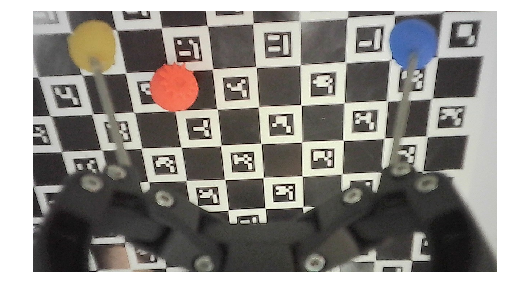

rp2040Send("cylinder on")

rp2040Send('servo_l 70')
rp2040Send('servo_r -160')

rp2040Send('servo_l 20')
rp2040Send('servo_r -100')

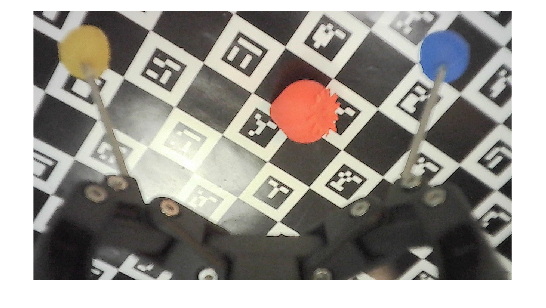

figure
imshow(dataRecord(256).img)

dataRecord(256).Jpos

ans =    -1.6110   -1.6488   -1.6767   -1.3870    1.5708    0.1036


delete(centroidHandle);

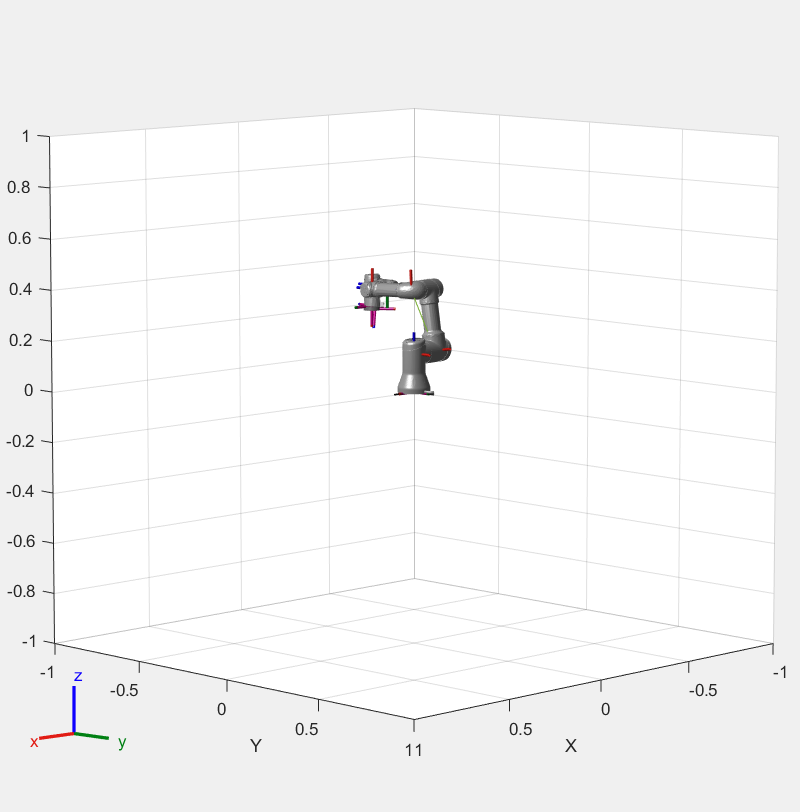

ans =   Axes (Primary) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


show(robot,qTargetN)

show(robot,qTarget)

ans =   Axes (Primary) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


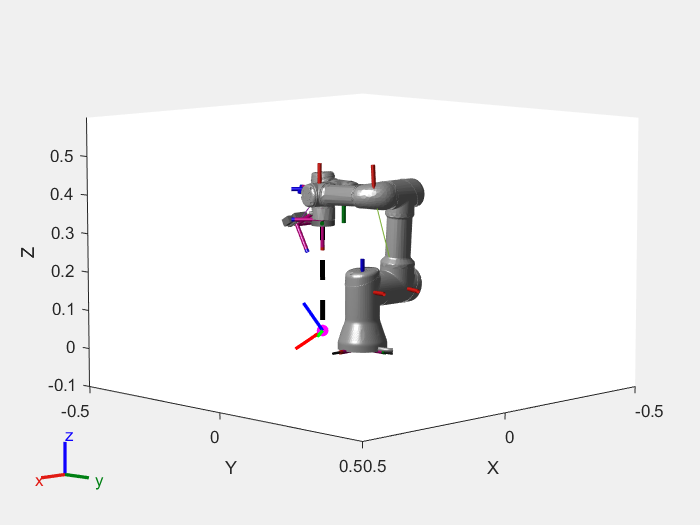


hold on
plot3([stwPos(1),stwPos(1)],[stwPos(2),stwPos(2)],[0.3,0],'LineWidth',3,'Color','black','LineStyle','--')
scatter3(stwPos(1),stwPos(2),0,50,'magenta','filled');
%scatter3(farStw(1),farStw(2),0,50,'black','filled');
quiver3(stwPos(1),stwPos(2),0, xLocal(1), xLocal(2), xLocal(3), 'r', 'LineWidth', 2); % X axis
quiver3(stwPos(1),stwPos(2),0, yLocal(1), yLocal(2), yLocal(3), 'g', 'LineWidth', 2); % Y axis
quiver3(stwPos(1),stwPos(2),0, zLocal(1), zLocal(2), zLocal(3), 'b', 'LineWidth', 2); % Z axis
hold off
grid off